% Non Linear CSTR Plant Simulation
clear all

% first set of parameters to run the Linear model (linearmodSS)
parameters1 = [102 350 -69.71*10^6 8.01 20.75*10^6 69.71*10^6 8314 801 3137 ...
    851 101 10.1 294 1000 4183 294 339.7022 323.7669 0.0842 0.04377 0.011];

% second set of parameters to run the Nonlinear plant
parameters2 = [102 350 -69.71*10^6 8.01 20.75*10^6 69.71*10^6 8314 801 3137 ...
    851 101 10.1 294 1000 4183 0.0842 339.7022 323.7669  0.04377 0.011];

% steady state values of output and input for plotting purposes
Tr_ss = 339.7022; % degree K
Fj_ss = 0.011; % m^3/s


% create linear spate space model with parameters1
[A,B,C,D] = NLmodss(parameters1);
eig(A)

ans =    -0.0407
   -0.0005
   -0.0034



sys = ss(A,B,C,D);
Gz = c2d(sys,100); % sample time is in seconds. 
[phi,gamma,Cz,Dz] = ssdata(Gz);

Amod = phi;
Bmod = gamma(:,2);
Bdis = gamma(:,1);

A_a = [Amod zeros(3,1);zeros(1,3) 1];
B_a = [Bmod;0];
C_a = [Cz 1];
L = [zeros(3,1);1];
tbeng = 0;
deltaT = 100;
time = tbeng:deltaT:10000; % simulation runs for 10000 sec)

% Plant disturbance is changes in feed flow rates
 kdist = (length(time)-1)/2;% 
  magdist =  input('Magnitude of disturbance (feedflow) [0 or 0.02 (m^3/s)] = ')

magdist = 0

  disturb = magdist*[zeros(kdist,1);ones((((length(time)-1)/2)+1),1)];
 
P = input('Prediction Horizon [20] ')

P = 20

M = input('Control Horizon [1] ')

M = 1

rsp = input('[Setpoint [0/1/10/20... degree K] ')

rsp = 10

Wu = 0;
Wy = eye(P,P);

[Sf,Sfd,Kmat,Cphi,S,Sd] = DynCal(P,M,Cz,phi,Bmod,Bdis,Wu);

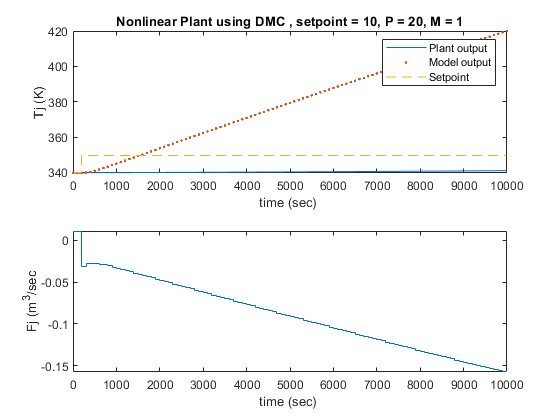



x0 = [0;0;0]; % initial conditions for the states
  xhat0 = [x0 ; 0]; 
  x(:,1) = x0;                % initial plant state
  y(1) = Cz*x0;
  xhat_old(:,1) = xhat0;      % initial state estimate
  xhat_new(:,1) = xhat0;      % initial state estimate
  xmod = x0;
  ymod(1) = Cz*xmod(:,1); % initial output estimate
  d(1) = 0;

u_ini = 0;

for k = 1:length(time)
    
    if k < length(time)
    
    % setpoint change at k = 3 (after one minute)
        
    if k < 3
        r(k) = 0;
        r_sp = ones(P,1)*r(k);
         free_resp = Cphi*xmod(:,k) + S(:,1)*u_ini + ones(P,1)*d(k);
          E = r_sp - free_resp; % error term
          du(:,k) = Kmat*E; % vector of calculated control moves
        
    else 
        r(k) = rsp; 
        r_sp = ones(P,1)*rsp;
       free_resp = Cphi*xmod(:,k) + S(:,1)*u(k-1) + ones(P,1)*d(k);
        E = r_sp - free_resp; % error term
        du(:,k) = Kmat*E; % vector of calculated control moves
        
    end

    if k == 1
       u(k) = u_ini + du(1,k); 
    else
        u(k) = u(k-1) + du(1,k);
    end

[tdummy,xdummy] = ode45(@(t,x) NLcstrplant(t,x,u(k),disturb(k),parameters2), [time(k) time(k+1)], x0);

x(:,k+1) = xdummy(end,:);
    y(:,k+1) = Cz*x(:,k+1);
    xhat_old(:,k+1) = A_a*xhat_old(:,k) + B_a*u(k);   % state estimate prediction
   
   xhat_new(:,k+1) = xhat_old(:,k+1) + L*(y(k+1)-C_a*xhat_old(:,k+1));
   xmod(:,k+1) = xhat_new(1:3,k+1);
   %xhat_old(:,k) = xhat_new(:,k);
   ymod(:,k+1) = Cz*xmod(:,k+1);  % output estimate
   d(:,k+1) = xhat_new(end,end);
      
    end
end
u(k) = u(end);
r(k) = r(end);

figure(100);
subplot(2,1,1)
plot(time,y+Tr_ss,time,ymod+Tr_ss,'.')
hold on
stairs(time,r+Tr_ss,'--')
hold off
title(['Nonlinear Plant using DMC , setpoint = ', num2str(rsp), ', P = ',num2str(P), ', M = ', num2str(M)])
ylabel('Tj (K)')
xlabel('time (sec) ')
legend('Plant output', 'Model output', 'Setpoint')


subplot(2,1,2)
stairs(time,u+Fj_ss)
ylabel('Fj (m^3/sec')
xlabel('time (sec) ')

A_aa = [Amod Bdis;zeros(1,3) 1];
B_aa = [Bmod;0];
C_aa = [Cz 0];
B_aw = [zeros(3,1);1];
sys_aa = ss(A_aa,[B_aa B_aw],C_aa,0,-1)


sys_aa =
 
  A = 
               x1          x2          x3          x4
   x1     0.01546   -0.005631  -0.0001317        1.82
   x2      0.2503      0.9308     0.02774       11.28
   x3     0.03553      0.1683      0.7344       1.025
   x4           0           0           0           1
 
  B = 
            u1       u2
   x1  0.01686        0
   x2   -4.358        0
   x3   -253.4        0
   x4        0        1
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
 
  D = 
       u1  u2
   y1   0   0
 
Sample time: 100 seconds
Discrete-time state-space model.




 Q  =1;% input('Enter Q [1] ') % input disturbance noise variance
%   Sensor covariance tuning parameter:
 R  =1; %input('Enter R [1] ') % suggestion: vary from 10 to 0.01

[Kest,L,Px,Mx,Z] = kalman(sys_aa,Q,R);

clear du; clear E; clear free_resp; clear x0;

x0 = [0;0;0]; % initial conditions for the states
  xhat0 = [x0 ; 0]; 
  x2(:,1) = x0;                % initial plant state
  y2(1) = Cz*x0;
  xhat_old2(:,1) = xhat0;      % initial state estimate
  xhat_new2(:,1) = xhat0;      % initial state estimate
  xmod2 = x0;
  ymod2(1) = Cz*xmod2(:,1); % initial output estimate
  d2(1) = 0;

u_ini = 0;
for k = 1:length(time)
    
    if k < length(time)
    
    % setpoint change at k = 3 (after one minute)
        
    if k < 3
        r2(k) = 0;
        r_sp = ones(P,1)*r2(k);
         free_resp = Cphi*xmod2(:,k) + Sf(:,1)*u_ini + Sfd(:,1)*d2(k);
          E = r_sp - free_resp; % error term
          du(k) = Kmat(1,:)*E; % vector of calculated control moves
        
    else 
        r2(k) = rsp; 
        r_sp = ones(P,1)*rsp;
       free_resp = Cphi*xmod2(:,k) + Sf(:,1)*u2(k-1) + Sfd(:,1)*d2(k);
        E = r_sp - free_resp; % error term
        du(k) = Kmat(1,:)*E; % vector of calculated control moves
        
    end

   
    if k == 1
       u2(k) = u_ini + du(k); 
    else
        u2(k) = u2(k-1) + du(k);
    end
    
[tdummy,xnew] = ode45(@(t,x) NLcstrplant(t,x,u2(k),disturb(k),parameters2), [time(k) time(k+1)], x0);

   x2(:,k+1) = xnew(end,:);
   y2(:,k+1) = Cz*x2(:,k+1);
   xhat_old2(:,k+1) = A_aa*xhat_old2(:,k) + B_aa*u2(k);   % state estimate prediction
   xhat_new2(:,k+1) = xhat_old2(:,k+1) + Mx*(y2(k+1)-C_aa*xhat_old2(:,k+1));
   xmod2(:,k+1) = xhat_new2(1:3,k+1);
   xhat_old2(:,k+1) = xhat_new2(:,k+1);
   ymod2(:,k+1) = Cz*xmod2(:,k+1);  % output estimate
   d2(:,k+1) = xhat_new2(end,end);
   
    end
end
u2(k) = u2(end);
r2(k) = r2(end);

figure(200);
subplot(2,1,1)
plot(time,y2+Tr_ss,time,ymod2+Tr_ss,'.')
hold on
stairs(time,r2+Tr_ss,'--')
hold off
title(['Nonlinear Plant using DMC , setpoint = ', num2str(rsp), ', P = ',num2str(P), ', M = ', num2str(M)])
ylabel('Tj (K)')
xlabel('time (sec) ')
legend('Plant output', 'Model output', 'Setpoint')


subplot(2,1,2)
stairs(time,u2+Fj_ss)
ylabel('Fj (m^3/sec')
xlabel('time (sec) ')
